Question 1

clear
qui=imread('quiche.jpg');

%[qui, rect]=imcrop(quiche)

[H,S,I]=rgbtohsi(qui);
y=0.299*qui(:,:,1)+0.587*qui(:,:,2)+0.114*qui(:,:,3)

y = 684×912 uint8 matrix
   24   28   28   26   24   28   28   27   19   22   27   23   17   14   20   27   28   23   17   16   19   22   25   25   19   16   21   26   21   19   24   26   29   30   30   30   29   22   19   27   32   29   25   22   26   31   34   32   30   27
   23   22   21   23   25   25   25   23   24   24   26   26   27   26   24   22   24   23   20   19   19   22   25   28   23   22   25   28   25   25   30   29   29   32   33   33   33   25   22   27   32   29   28   27   27   28   30   33   31   28
   25   21   20   24   26   24   23   25   28   24   21   24   30   32   28   21   19   23   24   24   23   24   26   29   27   26   27   27   27   30   31   26   30   32   34   36   35   28   25   28   32   29   31   31   29   25   27   33   31   28
   25   25   27   28   27   26   26   29   26   22   18   19   23   26   25   23   19   23   26   26   27   27   28   29   27   27   26   25   27   33   31   24   30   32   34   34   32   28   28   30   32   32   31   33  

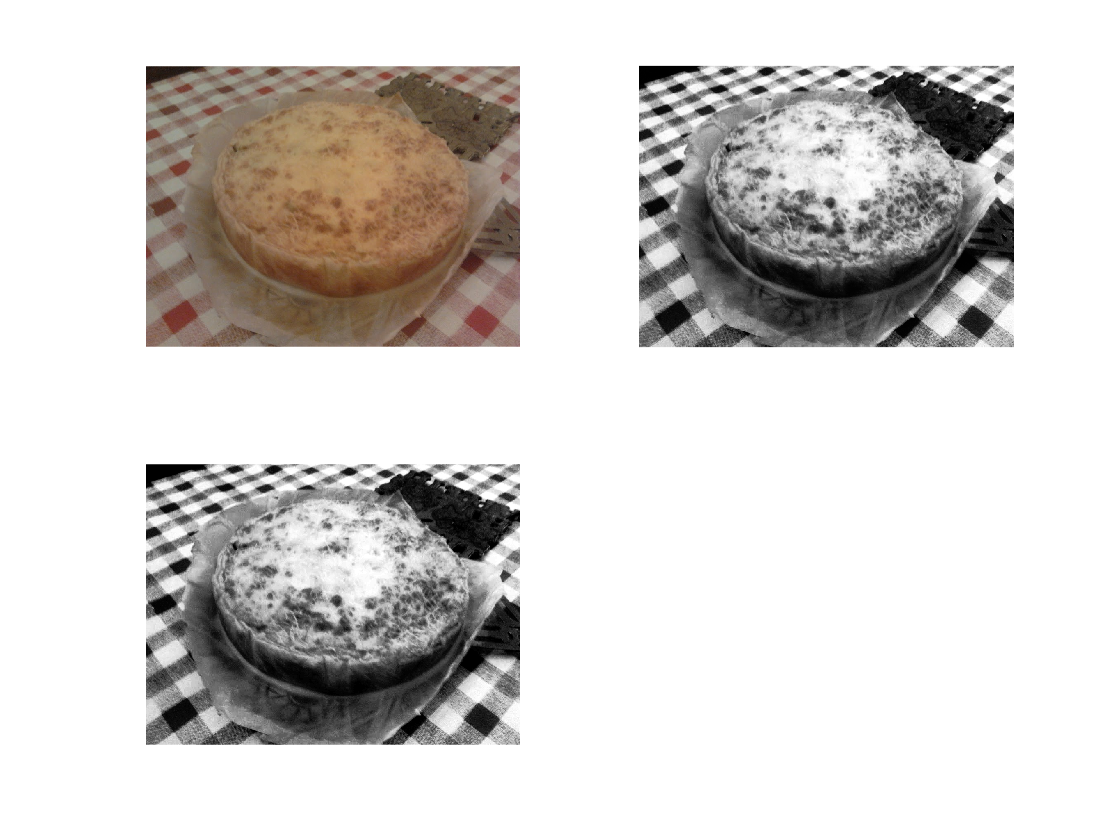

%y=uint8(y);

hist=histogramequalization(y);
E=histeq(y);
% 
figure;
subplot(221)
imshow(qui);
subplot(222)
imshow(hist,[]);
subplot(223)
imshow(E);

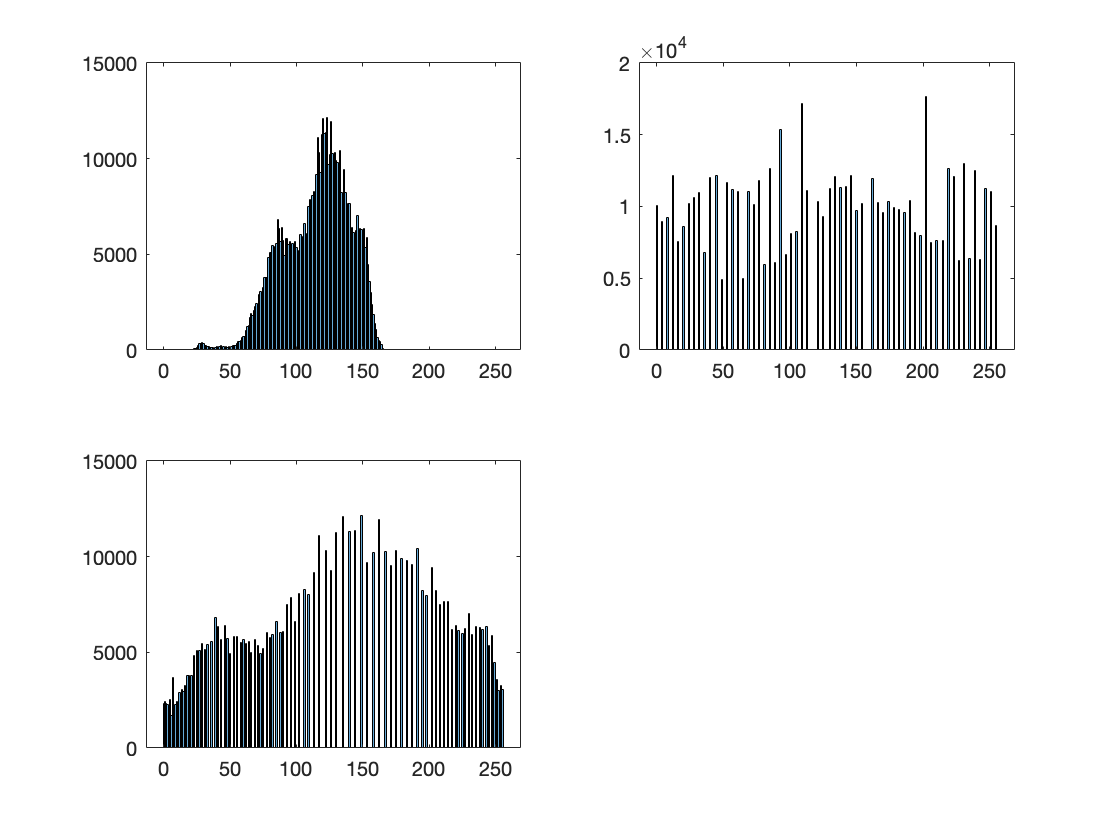


figure
subplot(221)
histogram(double(y),-0.5:255.5);
%axis([-0.5,255.5,0,7000]);axis off

subplot(222)
histogram(double(E(:)),-0.5:255.5);

subplot(223);
histogram(double(hist(:)),-0.5:255.5);

haar

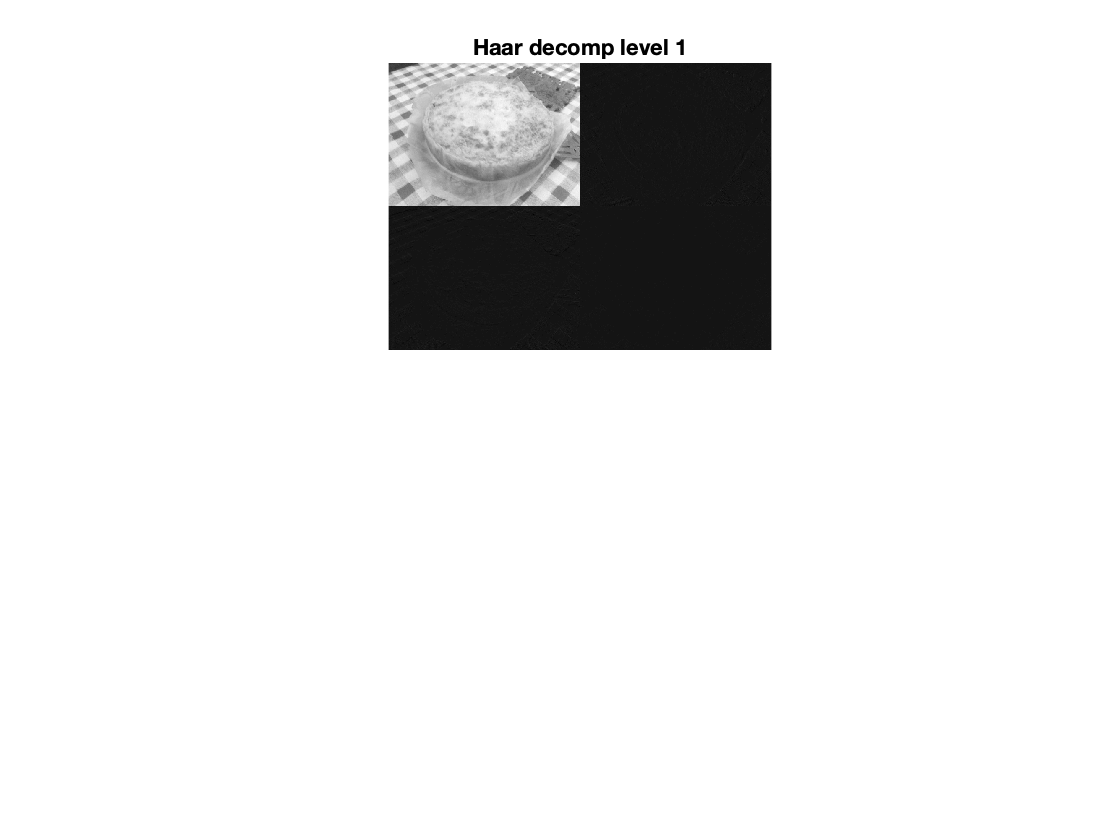

c=[1/sqrt(2),1/sqrt(2)];
d=[-1/sqrt(2),1/sqrt(2)];

[b1,h1,v1,d1]=dwlt2(y,c,d);

figure
subplot(211);
imagesc([b1 v1;h1 d1]);
colormap gray
axis image off
title('Haar decomp level 1')

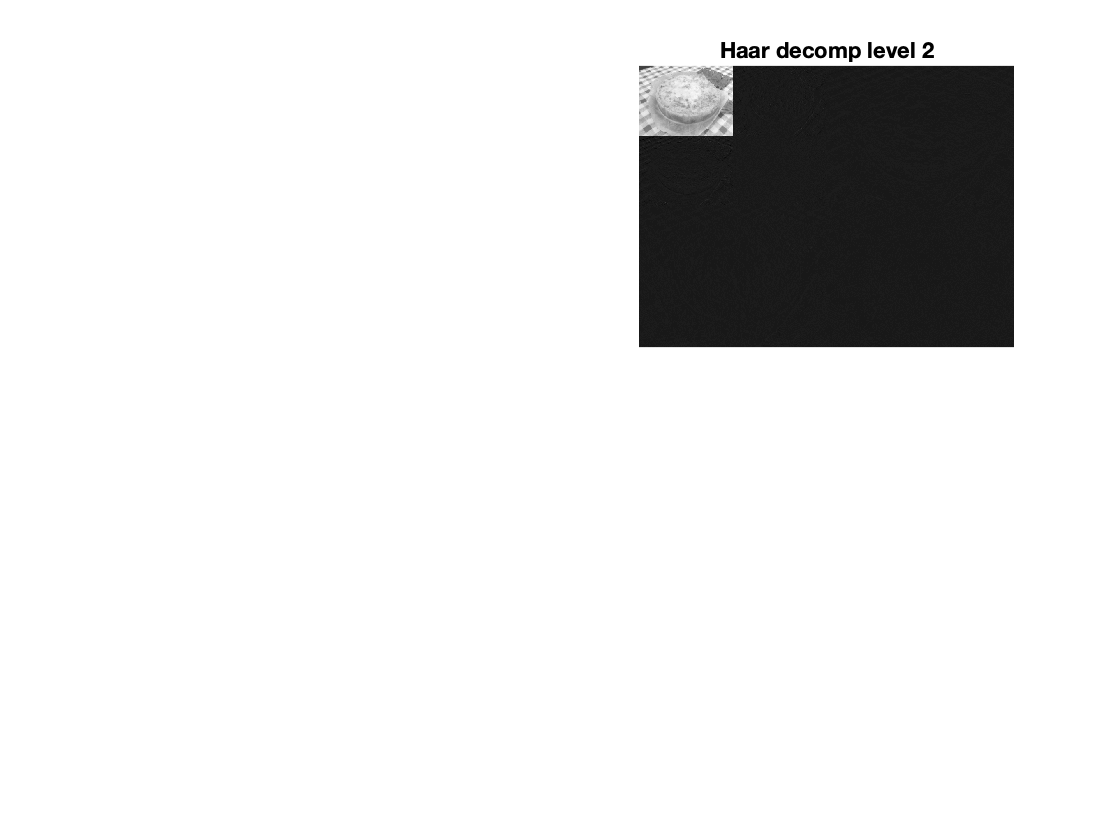


[b2,h2,v2,d2]=dwlt2(b1,c,d);
subplot(222);
imagesc([[b2 v2;h2 d2] h1; v1 d1]);
axis image off
title('Haar decomp level 2')

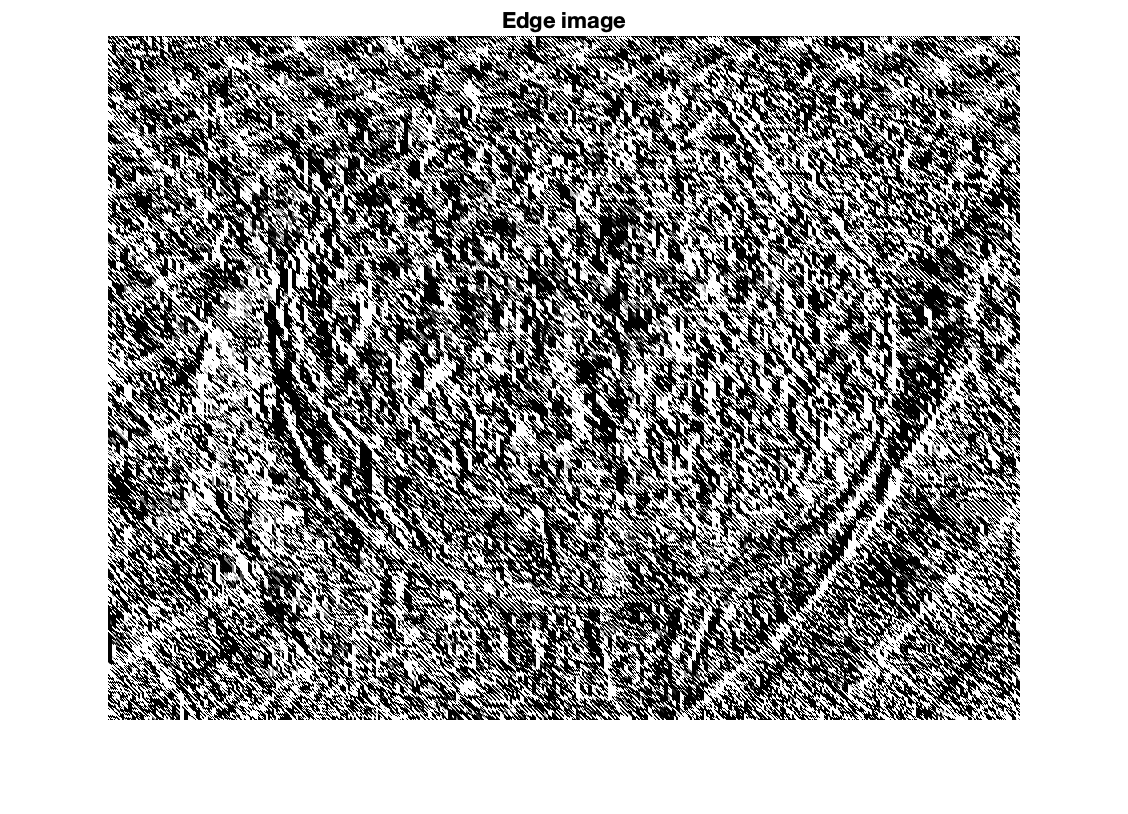

bs=zeros(size(b2));

alfa=1.0;

tau1=thresholding(alfa,h1,v1,d1);
tau2=thresholding(alfa,h2,v2,d2);

R2=idwlt2(bs,h2.*(abs(h2)>tau2),v2.*(abs(v2)>tau2),d2.*(abs(d2)>tau2),c,d);
R1=idwlt2(R2,h1.*(abs(h1)>tau1),v1.*(abs(v1)>tau1),d1.*(abs(d1)>tau1),c,d);

figure;
imshow(R1);
colormap gray
axis image off
title ('Edge image')

Question 2

clear
load('dataQ3.mat')

f=50;   

z1=0.3090+1i*0.9511 

z1 = 0.3090 + 0.9511i

z2=0.3090-1i*0.9511 

z2 = 0.3090 - 0.9511i


omega=log(z1)/(1i)

omega = 1.2567 - 0.0000i

omega=real(omega)

omega = 1.2567

nf=omega/(2*pi);
fs=f/nf

fs = 249.9941

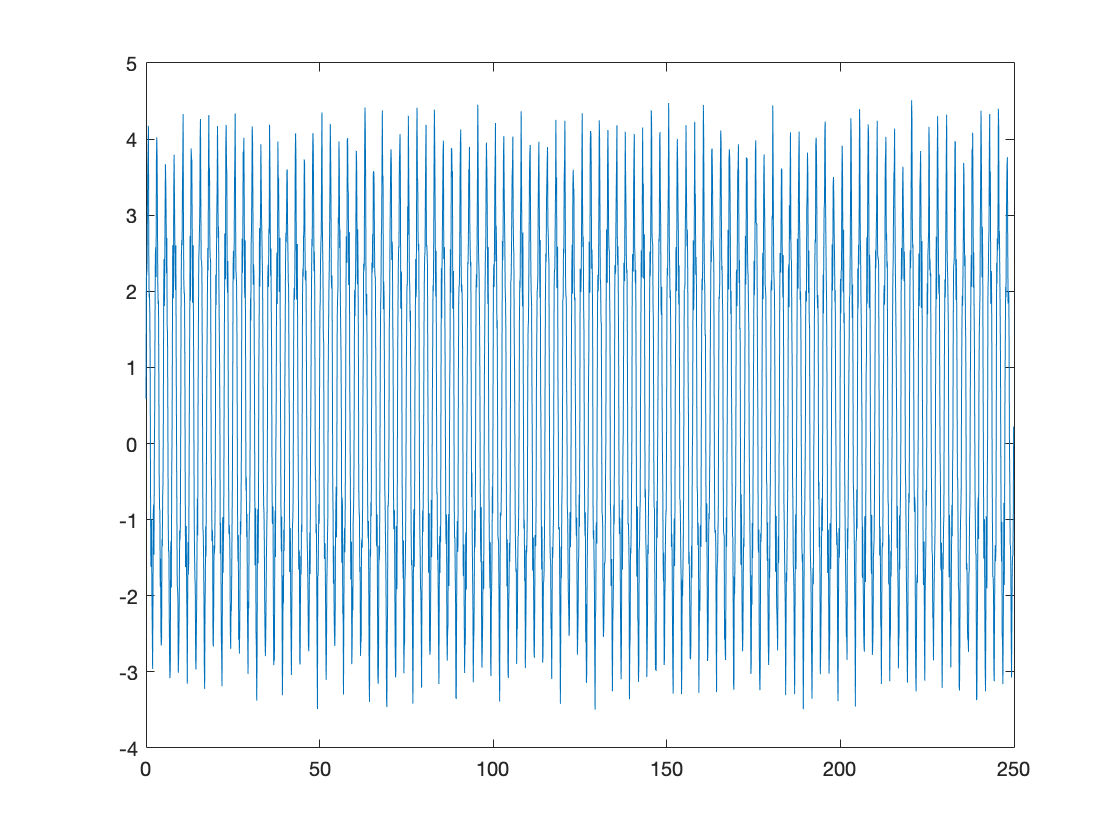


t = ((0:length(x)-1)*fs)./length(x);

figure
plot(t,x)

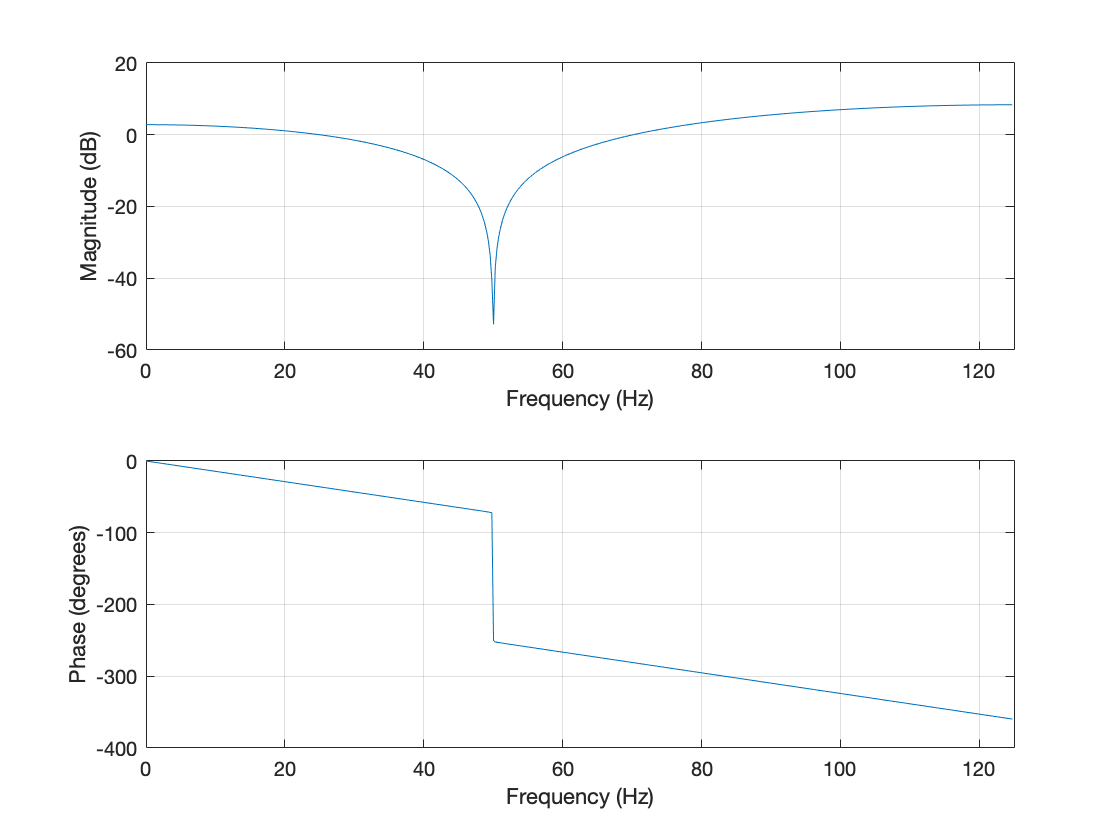


b=[1,-(z1+z2),z1*z2];

figure,
freqz(b,1,[],fs)

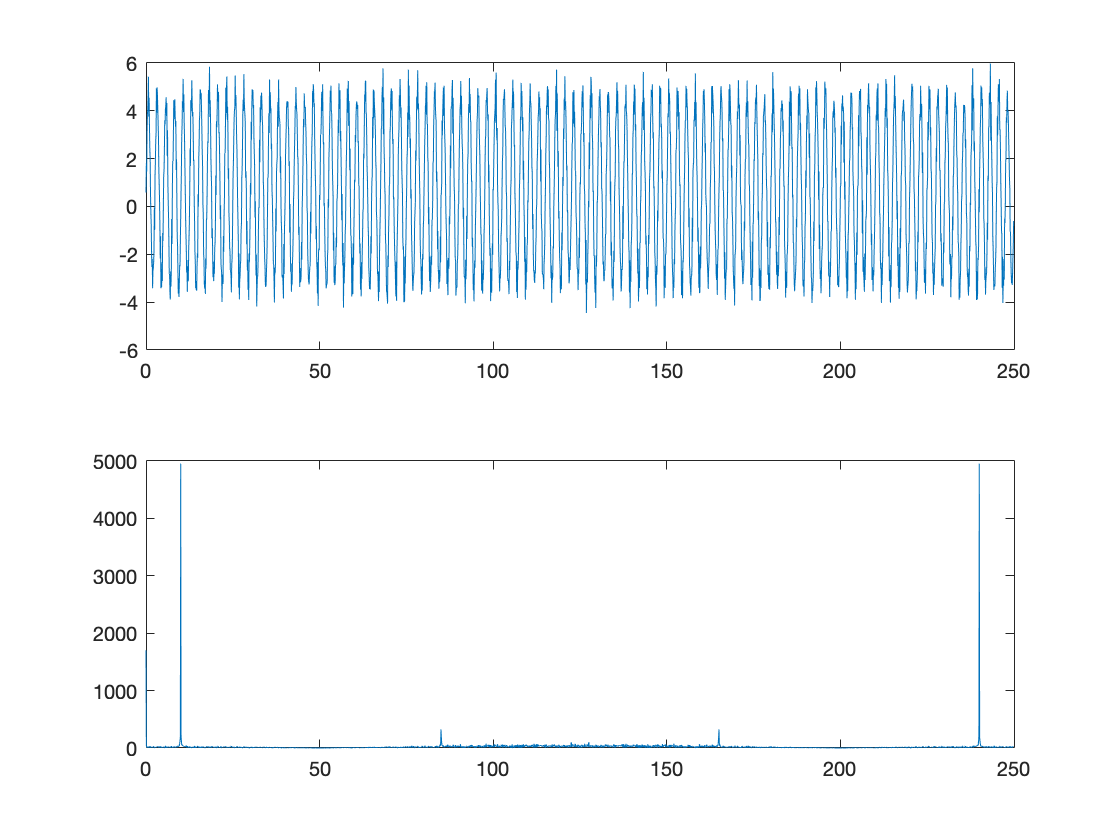


y=filter(b,1,x);

figure
subplot(211)
plot(t,y)

subplot(212)
plot(t,abs(fft(y)))

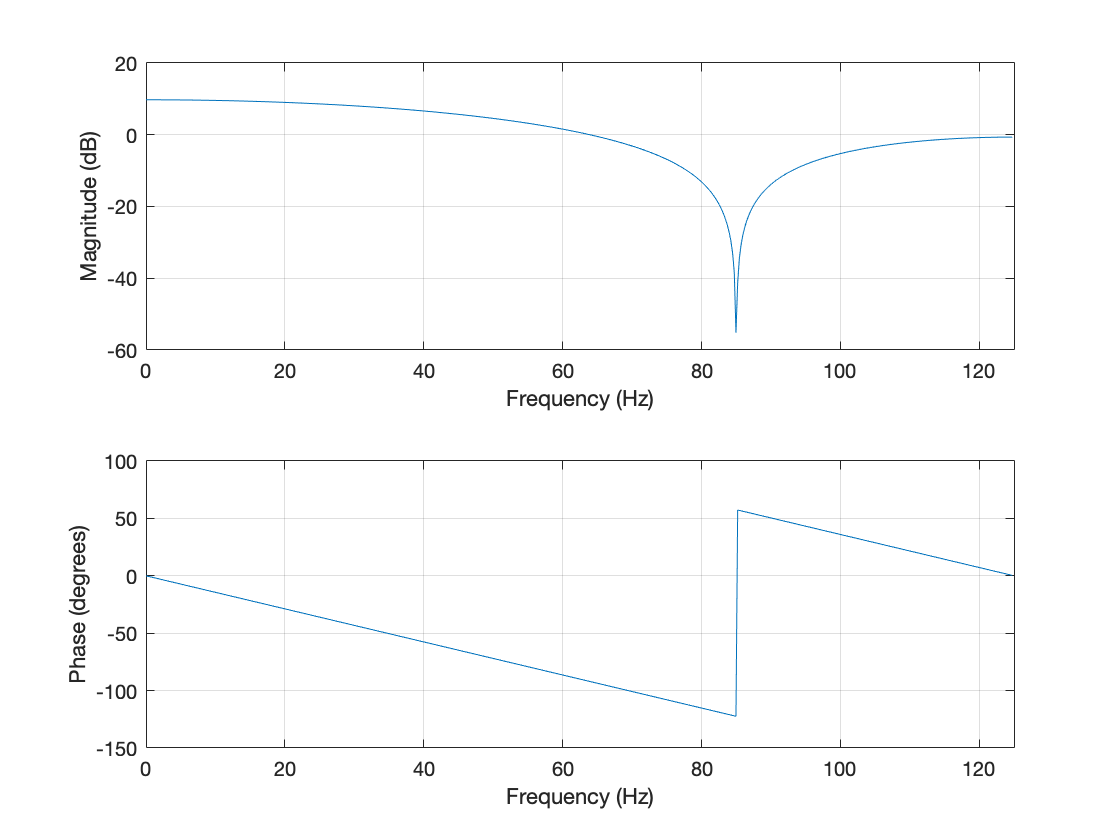


f2=85;

nf2=f2/fs;

omega2=2*pi*nf2;

z3=exp(1i*omega2);
z4=exp(-1i*omega2);

b2=[1,-(z3+z4),z3*z4];

%confoluting both filters
B=conv(b,b2);

figure,
freqz(b2,1,[],fs)

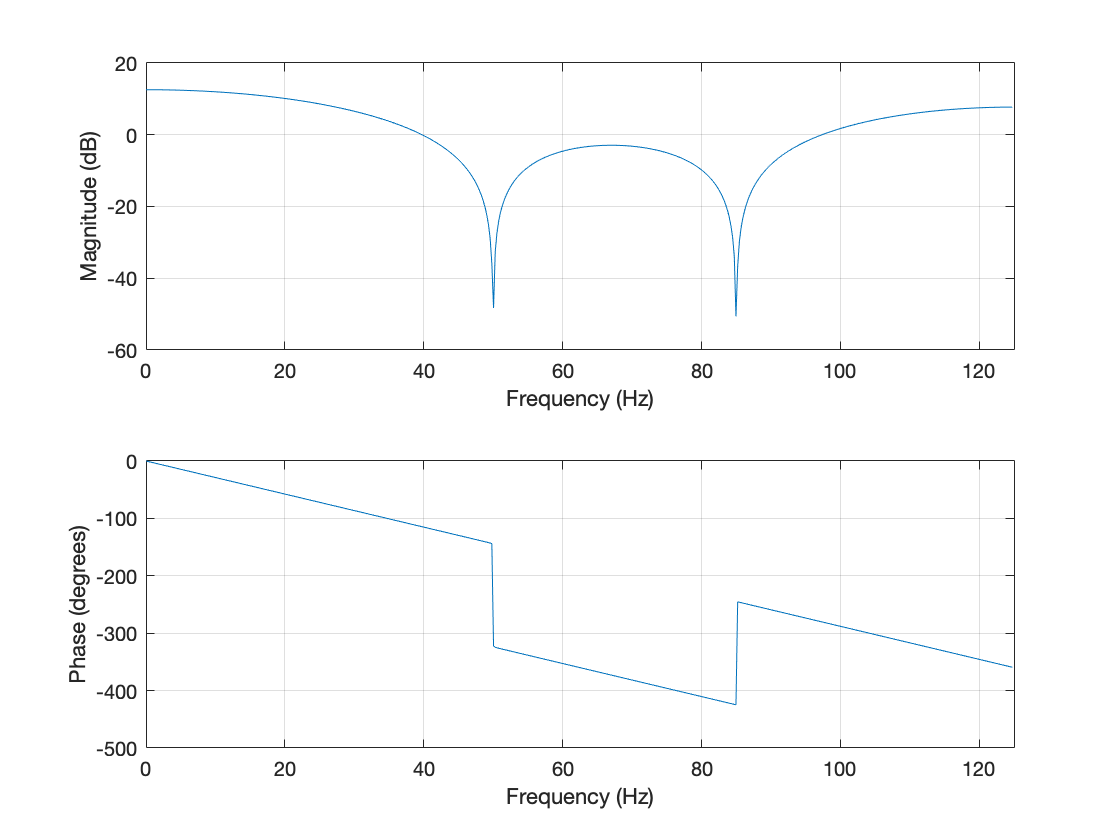

freqz(B,1,[],fs)

%axis([0 20000 -50 50])

y2=filter(b2,1,y)

y2 =     0.5877    2.4346    3.9853    6.4852    8.6221   11.2714   12.8065   14.4555   14.2140   14.0130   11.9330   10.4935    7.8722    5.0380    2.3152   -0.4832   -2.8847   -5.2848   -6.7623   -8.2875   -8.5377   -8.8583   -7.7913   -6.9700   -4.4218   -2.9103    0.1693    2.2229    5.9485    7.8151   10.9331   12.2829   14.1176   13.8842   13.9847   12.4286   10.6025    8.0441    5.4205    2.8068    0.4470   -2.7416   -4.3537   -6.9252   -7.5455   -9.6243   -8.5970   -8.9938   -6.7809   -5.7471


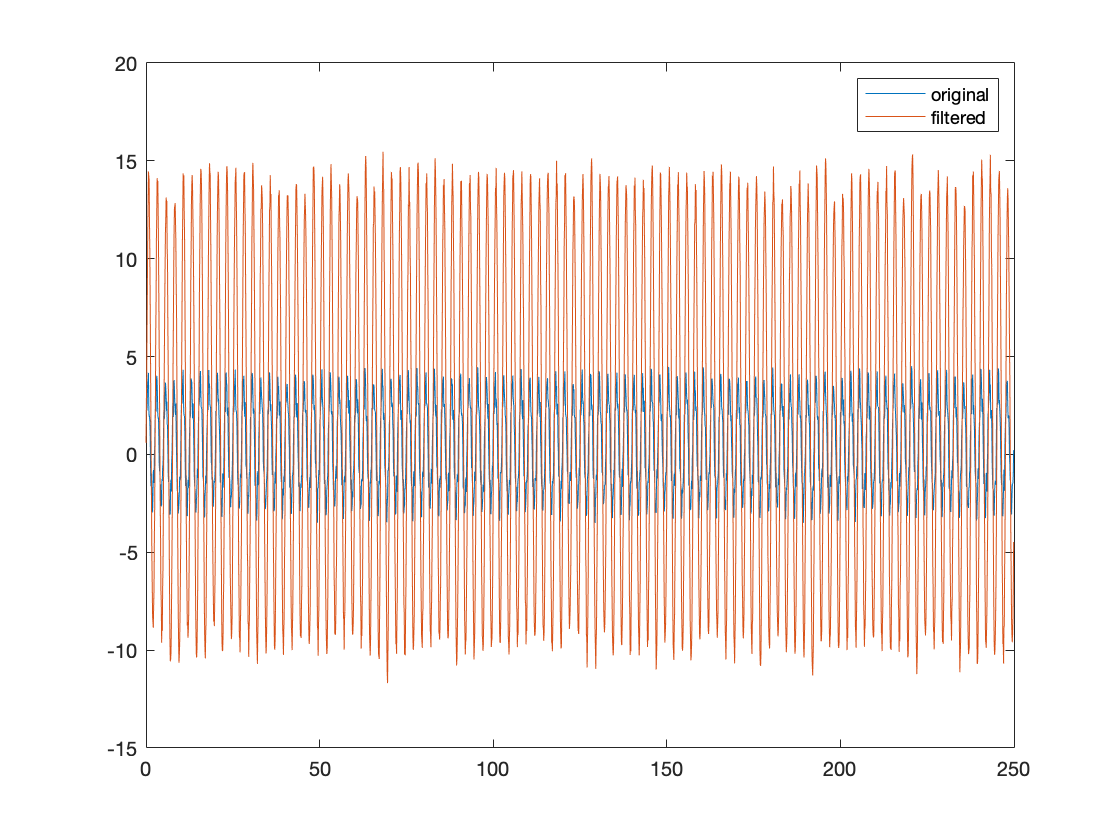


figure
plot(t,x,t,y2) 
legend('original','filtered')

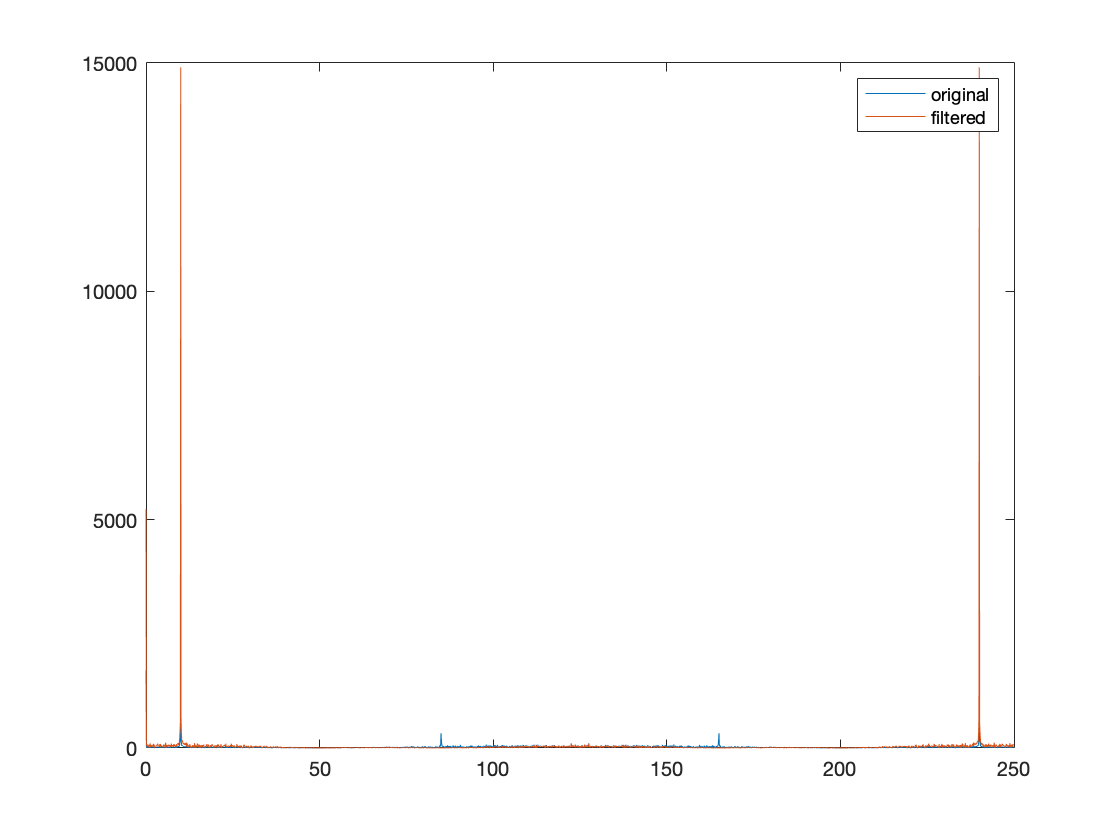


figure,
plot(t,abs(fft(y)),t,abs(fft(y2)));
legend('original','filtered')

Question 4

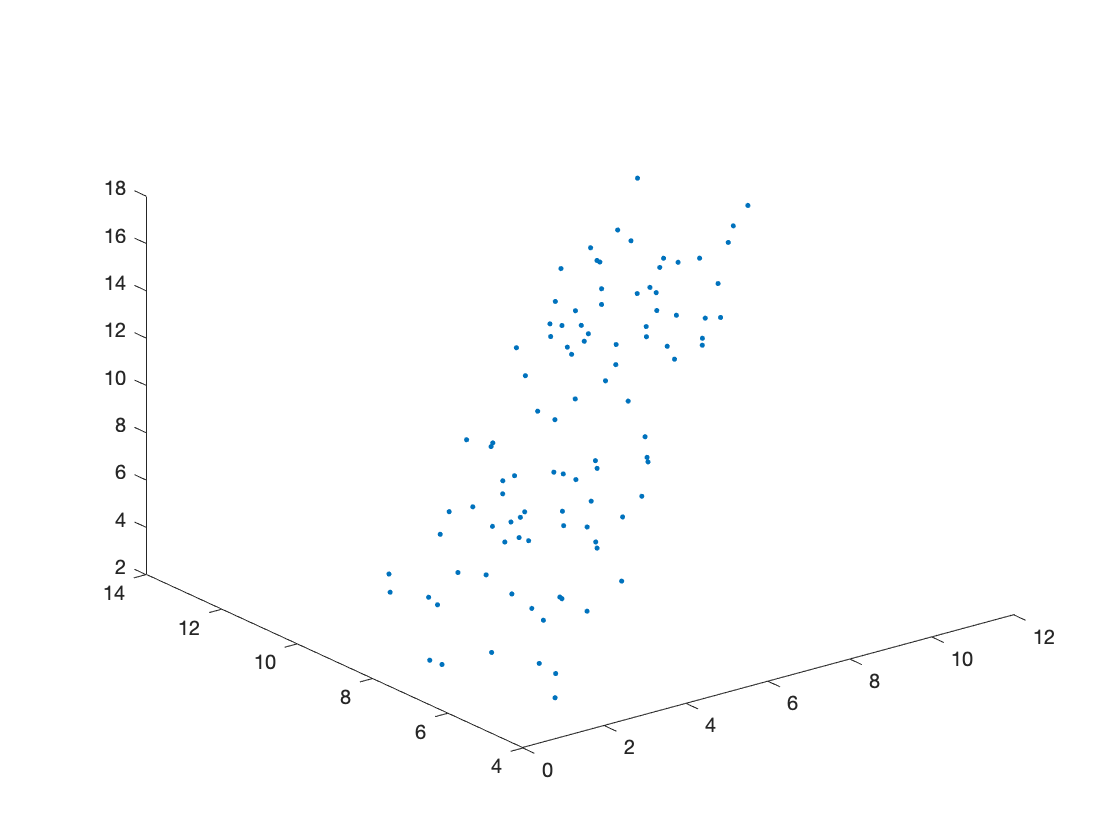

clear
load('dataQ4.mat')

size(X);

figure
plot3(X(1,:),X(2,:),X(3,:),'.')

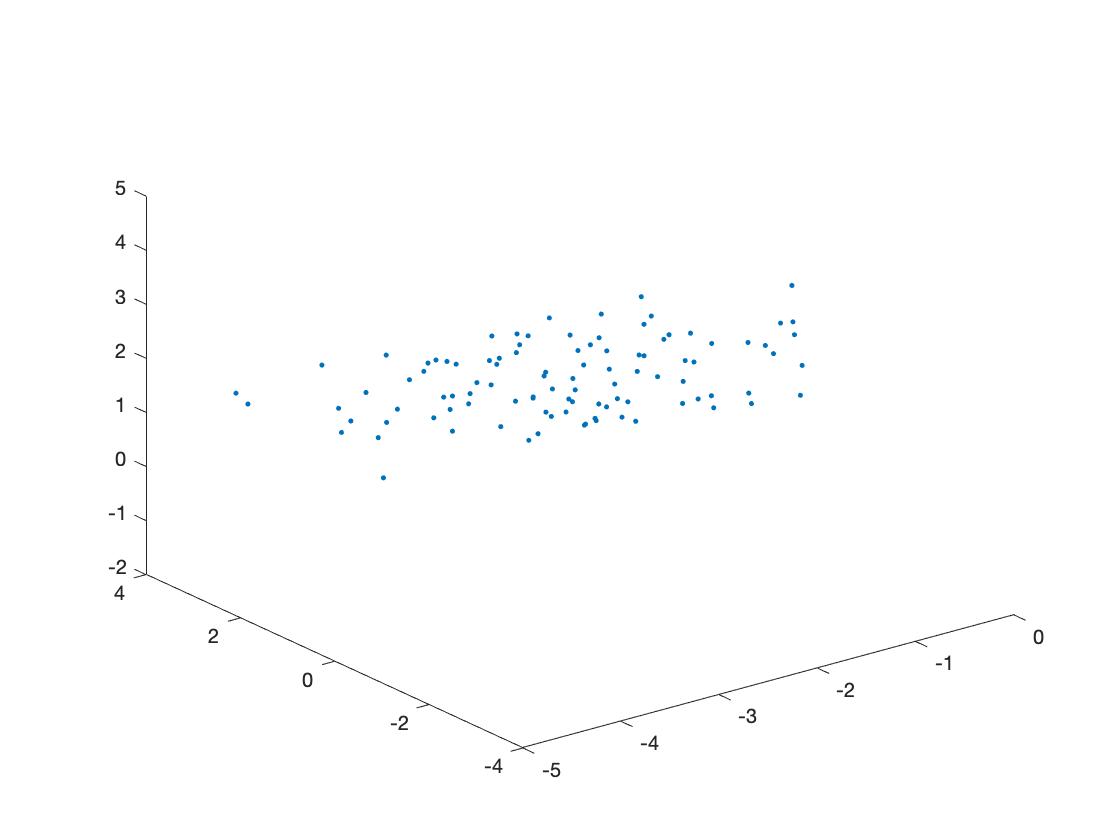


X0=bsxfun(@minus, X , mean(X,1));

figure
plot3(X0(1,:),X0(2,:),X0(3,:),'.')

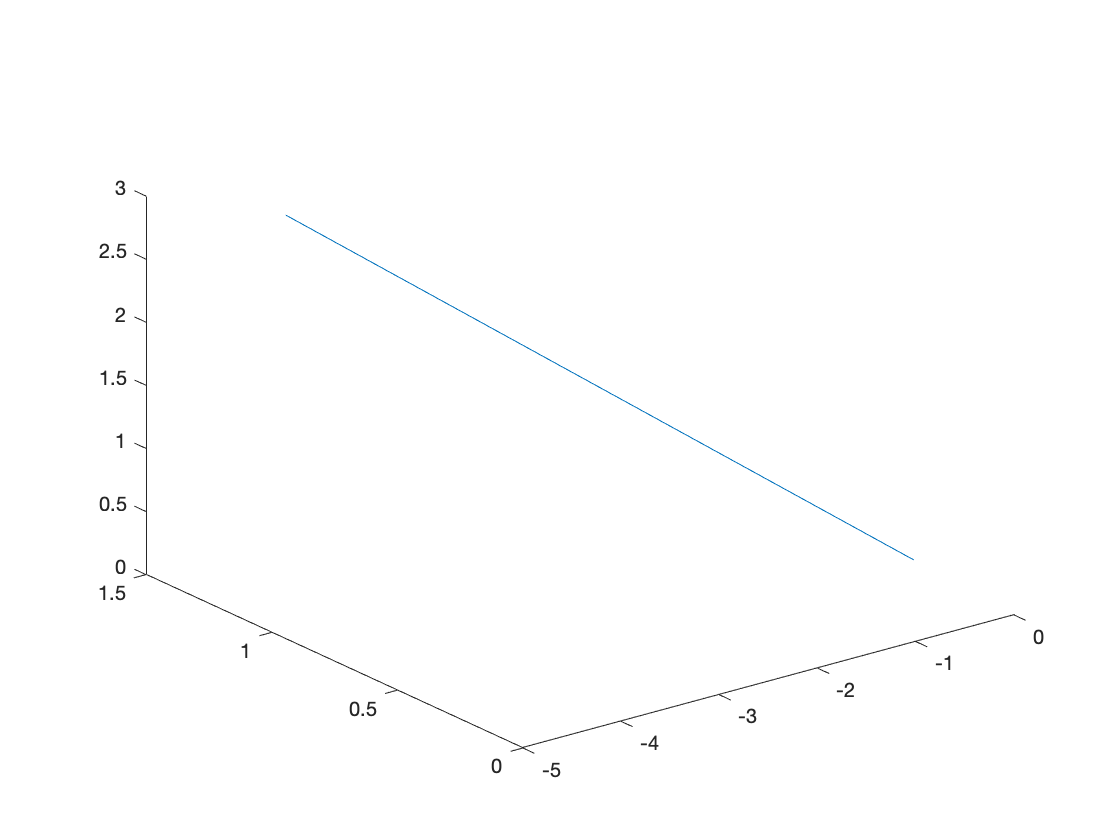


N = length(X0);
Rx = X0*X0'/N ;
[U, D] = eig(Rx);

D=fliplr(flipud(D));
U=fliplr(U);

A=U;
Z=U'*X0;

% A=U*D^(1/2)
% Z=D^(-1/2)*U'*X0

PC1=A(:,1)*pinv(A(:,1))*X0;
figure
plot3(PC1(1,:),PC1(2,:),PC1(3,:))


PCdata=bsxfun(@plus,PC1,mean(X,1)) 

PCdata =     0.6728    0.6978    1.9699    0.9700    1.8790    1.2519    1.1078    1.5452    1.6490    1.5502    2.0511    2.0304    2.0229    2.4827    1.9063    2.4266    2.4638    2.9502    2.5379    2.7185    2.3751    3.1239    3.3779    3.5136    2.8811    2.7736    2.7533    3.8374    3.4151    3.4044    3.5152    4.5008    4.0575    4.0391    4.0204    4.2058    3.6534    4.1145    4.3556    4.5118    4.0363    5.1950    4.7233    4.5017    5.4995    5.3467    5.4352    5.9076    5.6747    5.4579
    5.7650    6.1247    4.3396    4.2601    5.5839    4.1328    4.4219    3.4281    5.9466    5.4292    5.3938    5.5261    3.8933    4.9517    7.2406    6.9364    6.0169    6.5385    6.7933    6.2904    6.7880    5.1875    7.7395    7.2673    5.0580    5.3422    7.0059    7.4728    7.0955    8.4292    6.7029    6.4964    6.5810    5.5751    6.8422    8.5822    7.2033    7.0366    6.3778    7.7974    7.9877    8.4610    7.8709    6.8280    9.0139    9.7349    7.7421    8.8121    7.6067

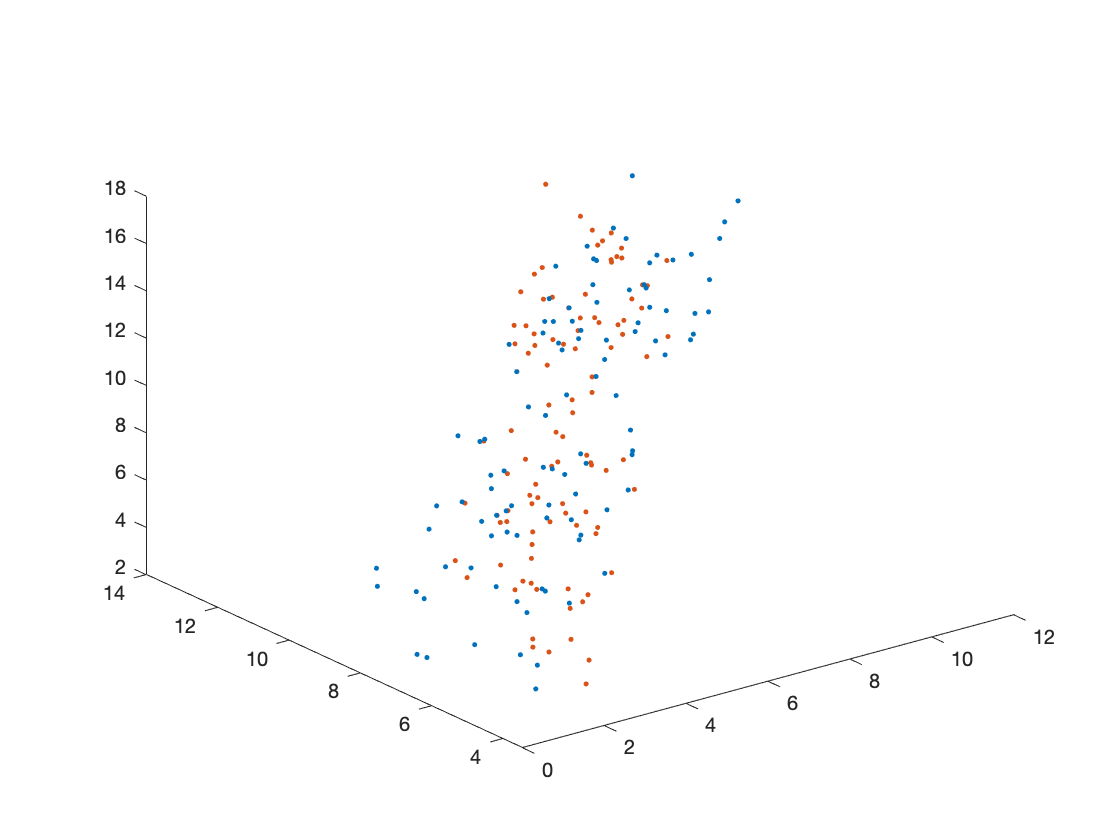


figure
plot3(X(1,:),X(2,:),X(3,:),'.')
hold on
plot3(PCdata(1,:),PCdata(2,:),PCdata(3,:),'.')

Question 5


% 
% syms c
% px=solve(h2==-c*(1-c)/(sqrt(2)*(1+c^2)),c)

p=[-1,(sqrt(2)-1/2),-3/50]

p =    -1.0000    0.9142   -0.0600


r=roots(p)

r =     0.8430
    0.0712


q=r(1)

q = 0.8430

p=sqrt(2)-q-1/2;
Lp=[3/5,p,-1/10,q]

Lp =     0.6000    0.0712   -0.1000    0.8430


b)

% h0+h1+h2+h3+h4+h5==sqrt(2);
% h0*h2+h1*h3+h2*h4+h3*h5==0;
% h0*h4+h1*h5==0
% h0-h1+h2-h3+h4-h5==0
% h1-2*h2+3*h3-4*h4+5*h5==0
% h1-4*h2+9*h3-16*h4+25*h5==0

% syms h0 h1 h2 h3 h4 h5
% eqn=[h0+h1+h2+h3+h4+h5==sqrt(2),
%     h0*h2+h1*h3+h2*h4+h3*h5==0,
%     h0*h4+h1*h5==0,
%     h0-h1+h2-h3+h4-h5==0,
%     h1-2*h2+3*h3-4*h4+5*h5==0,
%     h1-4*h2+9*h3-16*h4+25*h5==0]
% 
% px=solve(eqn,[h0 h1 h2 h3 h4 h5], 'ReturnConditions', true)

H0db6=(sqrt(2)/32)*[1+sqrt(10)+sqrt(5+2*sqrt(10)) 5+sqrt(10)+3*sqrt(5+2*sqrt(10)) 10-2*sqrt(10)+2*sqrt(5+2*sqrt(10)) 10-2*sqrt(10)-2*sqrt(5+2*sqrt(10)) 5+sqrt(10)-3*sqrt(5+2*sqrt(10)) 1+sqrt(10)-sqrt(5+2*sqrt(10))] % DB6 low-pass

H0db6 =     0.3327    0.8069    0.4599   -0.1350   -0.0854    0.0352


H1db6=fliplr(H0db6).*[1 -1 1 -1 1 -1] % DB6 high-pass (alternating flip)

H1db6 =     0.0352    0.0854   -0.1350   -0.4599    0.8069   -0.3327


Question 6

clear

load('dataQ7.mat')

v=y

v =     0.0645    0.0607    0.0463    0.1519    0.0778    0.1477    0.1425    0.0388   -0.0067   -0.0121    0.1017    0.0564    0.1502    0.0504   -0.0041    0.0717    0.1500    0.0941    0.0403    0.0130    0.1306    0.1499    0.0361   -0.0261   -0.0038    0.0743   -0.0048    0.0151    0.0476    0.0231    0.0156    0.0424   -0.0039   -0.0466    0.0788   -0.0214    0.1076    0.0297    0.0149    0.1007    0.1033   -0.0082   -0.0161   -0.0013    0.0930    0.1394    0.0765    0.0107    0.1230    0.1638


n=length(v);

fl=dbfilter(1)


Equation solved at initial point.

fsolve completed because the vector of function values at the initial point
is near zero as measured by the selected value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



fl =     0.5000    0.5000


fh=fliplr(fl).*[1 -1]

fh =     0.5000   -0.5000



[a1,b1]=discreteWaveletTransform(v,fl,fh);
[a2,b2]=discreteWaveletTransform(a1,fl,fh);
[a3,b3]=discreteWaveletTransform(a2,fl,fh);
[a4,b4]=discreteWaveletTransform(a3,fl,fh);

N=length(b1)+length(b3)+length(b3);

sigma=mad(b1,1)/0.6745;
lambda=sigma*sqrt(2*log(N));

b1s=softThresholding(b1,lambda);
b2s=softThresholding(b2,lambda);
b3s=softThresholding(b3,lambda);
b4s=softThresholding(b4,lambda);

a33 = invDaubechies1D(a4,b4s,fl,fh);
a22 = invDaubechies1D(a33,b3s,fl,fh);
a11 = invDaubechies1D(a22,b2s,fl,fh);
rec_sig = invDaubechies1D(a11,b1s,fl,fh);

rec_sig=rec_sig(1:n);
rec_sig=rec_sig'

rec_sig =     0.0711    0.0711    0.0711    0.0711    0.0711    0.0711    0.0711    0.0711    0.0711    0.0711    0.0711    0.0711    0.0711    0.0711    0.0711    0.0711    0.0498    0.0498    0.0498    0.0498    0.0498    0.0498    0.0498    0.0498    0.0498    0.0498    0.0498    0.0498    0.0498    0.0498    0.0498    0.0498    0.0411    0.0411    0.0411    0.0411    0.0411    0.0411    0.0411    0.0411    0.0411    0.0411    0.0411    0.0411    0.0411    0.0411    0.0411    0.0411    0.0914    0.0914


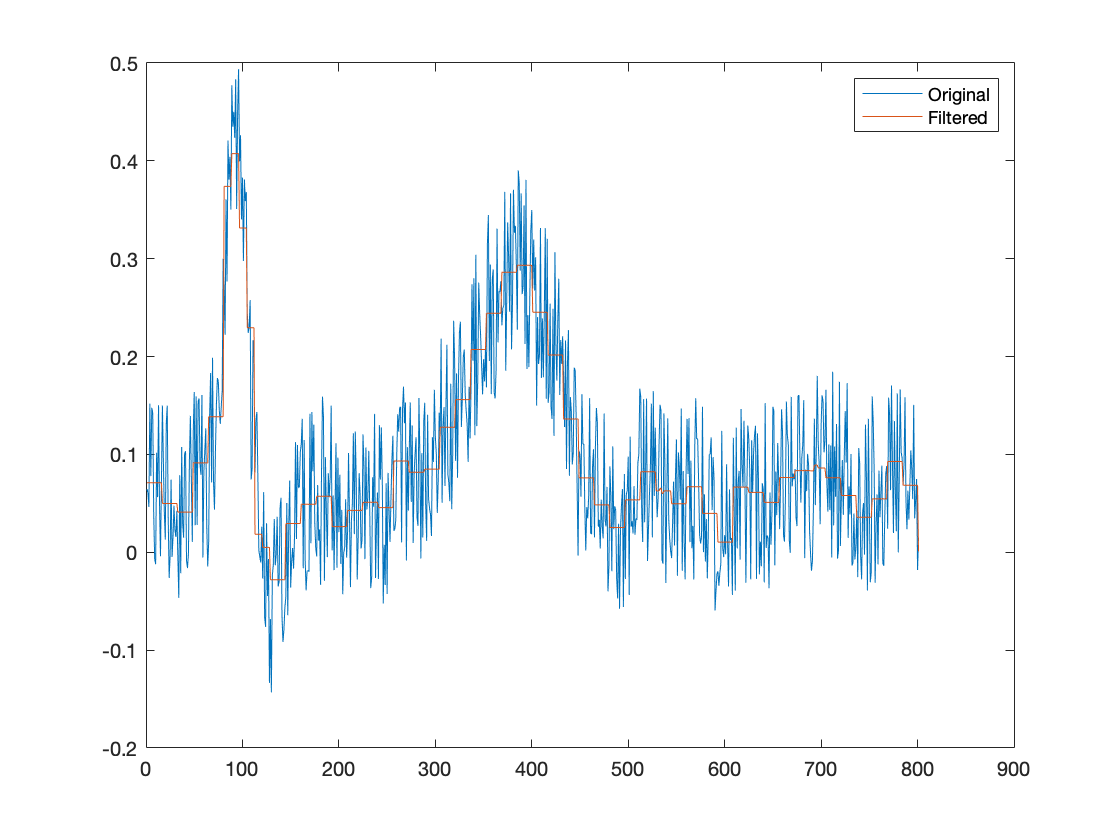


figure
plot(v)
hold on
plot(rec_sig)
legend('Original','Filtered')